# Kinetic Parameter Estimation and Uncertainty Quantification for a Batch Reaction A → B

Project 01: Chemical Engineering Research & Simulation Roadmap

Author: Lyna LAZZOUZI

École Nationale Polytechnique d'Alger (Chemical Engineering)

Tools: MATLAB, Optimization Toolbox (ode45, lsqnonlin), Statistics and Machine Learning Toolbox (nlparci)

## 1. Introduction

In chemical reaction engineering, sizing or operating a reactor requires knowing the reaction rate, and therefore the kinetic parameters: rate constant k, reaction order n and activation energy Ea. These parameters cannot be measured directly. They are inferred from concentration-versus-time measurements by fitting a model to the data.

This project builds and validates this approach on synthetic data. Since the true parameters are known, we can check that the method recovers them and, above all, quantify the effect of measurement noise on the quality of the estimation.

Objectives: - Simulate a first-order reaction A → B in a closed (batch) reactor and generate noisy data. - Estimate k by nonlinear least squares (ode45 + lsqnonlin). - Quantify the uncertainty (95 % confidence interval) and validate the fit (residuals, RMSE, R²). - Study the influence of the noise level with a Monte Carlo study. - Estimate k0 and Ea from data at several temperatures (Arrhenius law). - Extend to a free reaction order n and discuss parameter identifiability.

## 2. Mathematical model

Assumptions: closed (batch) reactor, isothermal, perfectly mixed, constant volume, a single reaction A → B.

Mass balance on A: dCA/dt = -k · CA^n, with CA(0) = CA0

For first order (n = 1), the analytical solution is: CA(t) = CA0 · exp(-k · t) i.e.: ln CA = ln CA0 - k · t (a straight line of slope -k)

Temperature dependence (Arrhenius law): k(T) = k0 · exp(-Ea / (R · T)) i.e.: ln k = ln k0 - (Ea / R) · (1/T)

Reparametrization used for the global fit: k0 and Ea are strongly correlated, because k0 is an extrapolation to 1/T = 0, far from the data. We therefore work around a reference temperature Tref:

Numerical method: the differential equation is integrated with ode45 (Runge-Kutta 4-5, tolerances 1e-8). Parameter estimation minimizes the sum of squared residuals with lsqnonlin (trust-region algorithm).

## 3. Setup

Environment initialization. The random number generator is fixed (rng) so that results are reproducible. The output folders are created if they do not exist. The src folder contains the project functions.

clear; close all; clc;
rng(1);
addpath('src');
for d = {'data','figures','results'}
    if ~exist(d{1}, 'dir'), mkdir(d{1}); end
end
R = 8.314;   % ideal gas constant (J/mol/K)

## 4. Validation of the numerical solver

Before estimating anything, we check that the numerical model is correct by comparing it with the exact analytical solution. If ode45 reproduces CA0·exp(-k·t) to about 1e-8, we can trust it for the rest of the study (and for kinetics that have no analytical solution).

t = (0:1:20)';  k_test = 0.35;  CA0_test = 2;
CA_num = model_first_order(k_test, t, CA0_test);
CA_ana = CA0_test*exp(-k_test*t);
fprintf('Max error ode45 vs analytical solution: %.2e mol/L\n', max(abs(CA_num - CA_ana)));

Max error ode45 vs analytical solution: 7.51e-10 mol/L


## 5. Synthetic data generation

We set the true parameters (k = 0.35 min^-1, CA0 = 2 mol/L), compute the exact curve, then add 3 % relative Gaussian noise. Relative noise is realistic: the error of an analyzer is often proportional to the measured value. The estimation algorithm does not know k_true. It has to recover it from the noisy data alone.

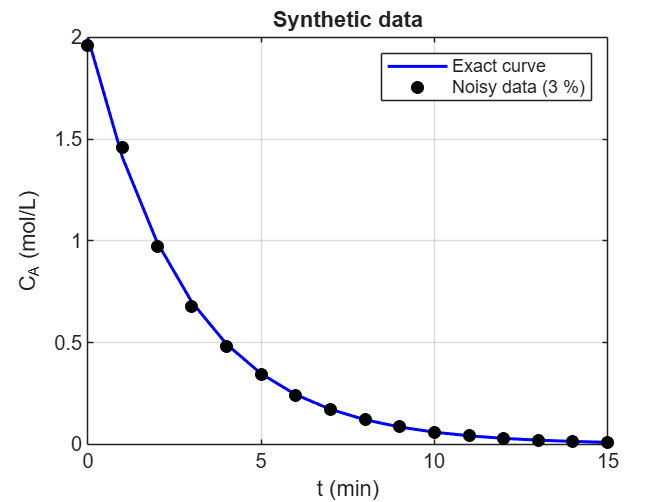

k_true = 0.35;      % 1/min
CA0    = 2.0;       % mol/L
t      = (0:1:15)'; % min
sigma  = 0.03;      % relative standard deviation of the noise

CA_exact = CA0*exp(-k_true*t);
CA_data  = CA_exact .* (1 + sigma*randn(size(t)));
CA_data  = max(CA_data, 1e-6);   % no negative concentrations
writematrix([t CA_data], 'data/data_isothermal.csv');

figure;
plot(t, CA_exact, 'b-', 'LineWidth', 1.5); hold on
plot(t, CA_data, 'ko', 'MarkerFaceColor', 'k');
xlabel('t (min)'); ylabel('C_A (mol/L)'); grid on
legend('Exact curve', 'Noisy data (3 %)');
title('Synthetic data');

## 6. Estimation of k by nonlinear least squares

The residual is the vector of differences between the model (with a candidate k) and the data. lsqnonlin looks for the k that minimizes the sum of squares of these differences: it starts from an initial guess, measures how the differences change when k moves (the Jacobian), corrects k, and iterates until convergence. The lower bound k >= 0 expresses a physical constraint. The 95 % confidence interval is computed by nlparci from the Jacobian: it indicates how far off k could be, given the noise and the number of points.

res_fun = @(k) model_first_order(k, t, CA0) - CA_data;
k_guess = 0.1;
opts = optimoptions('lsqnonlin', 'Display', 'off', ...
        'FunctionTolerance', 1e-12, 'StepTolerance', 1e-12);
[k_hat, resnorm, residual, exitflag, ~, ~, J] = lsqnonlin(res_fun, k_guess, 0, [], opts);

RMSE = sqrt(mean(residual.^2));
R2   = 1 - sum(residual.^2)/sum((CA_data - mean(CA_data)).^2);
CI   = nlparci(k_hat, residual, 'jacobian', J);

fprintf('True k      = %.4f 1/min\n', k_true);

True k      = 0.3500 1/min


fprintf('Estimated k = %.4f 1/min\n', k_hat);

Estimated k = 0.3527 1/min


fprintf('95 %% CI     = [%.4f ; %.4f]\n', CI(1), CI(2));

95 % CI     = [0.3445 ; 0.3610]


fprintf('Relative error on k = %.2f %%\n', 100*abs(k_hat - k_true)/k_true);

Relative error on k = 0.78 %


fprintf('RMSE = %.4f mol/L | R2 = %.4f | exitflag = %d (1 to 4: converged)\n', RMSE, R2, exitflag);

RMSE = 0.0179 mol/L | R2 = 0.9990 | exitflag = 1 (1 to 4: converged)


fprintf('The true k lies within the confidence interval: %s\n', string(k_true >= CI(1) && k_true <= CI(2)));

The true k lies within the confidence interval: true


## 7. Comparison with the linearized regression

Classical method: plot ln(CA) versus t and fit a straight line whose slope equals -k. It is simple and instructive, but it only works for kinetics that can be linearized. We compare it here with the nonlinear fit.

pol   = polyfit(t, log(CA_data), 1);
k_lin = -pol(1);
fprintf('k (nonlinear fit)        = %.4f 1/min\n', k_hat);

k (nonlinear fit)        = 0.3527 1/min


fprintf('k (linearization ln CA)  = %.4f 1/min\n', k_lin);

k (linearization ln CA)  = 0.3491 1/min


fprintf('True k                   = %.4f 1/min\n', k_true);

True k                   = 0.3500 1/min


## 8. Validation plots: fit and residuals

Left: data, fitted model and true curve. Right: residuals. A good model leaves residuals scattered around zero with no trend. A pattern (for example positive then negative) would reveal an inadequate model, for instance a wrong reaction order.

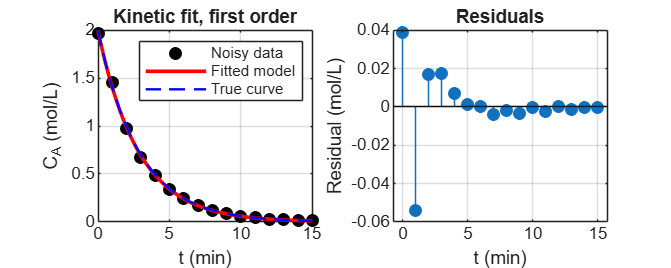

t_fine = linspace(0, max(t), 200)';
CA_fit = model_first_order(k_hat, t_fine, CA0);

figure('Position', [100 100 1000 400]);
subplot(1,2,1)
plot(t, CA_data, 'ko', 'MarkerFaceColor', 'k'); hold on
plot(t_fine, CA_fit, 'r-', 'LineWidth', 1.8)
plot(t_fine, CA0*exp(-k_true*t_fine), 'b--', 'LineWidth', 1.2)
xlabel('t (min)'); ylabel('C_A (mol/L)'); grid on
legend('Noisy data', 'Fitted model', 'True curve');
title('Kinetic fit, first order');

subplot(1,2,2)
stem(t, residual, 'filled'); yline(0, 'k-');
xlabel('t (min)'); ylabel('Residual (mol/L)'); grid on
title('Residuals');

exportgraphics(gcf, 'figures/fig01_fit_k.png', 'Resolution', 300);

## 9. Influence of noise: Monte Carlo study

A single noisy data set gives a single estimated k, and we cannot tell whether we were lucky. We therefore repeat the estimation 200 times for each noise level, with a different noise draw each time. This gives a distribution of estimated k values: its mean gives the bias and its standard deviation gives the uncertainty. This cell performs 1000 fits and can take a few minutes on MATLAB Online.

rng(2);
sigmas = [0.01 0.03 0.05 0.10 0.20];
Nmc    = 200;
k_est  = zeros(Nmc, numel(sigmas));
opts_q = optimoptions('lsqnonlin', 'Display', 'off');

tic
for j = 1:numel(sigmas)
    for i = 1:Nmc
        d = CA_exact .* (1 + sigmas(j)*randn(size(t)));
        d = max(d, 1e-6);
        k_est(i,j) = lsqnonlin(@(k) model_first_order(k, t, CA0) - d, 0.1, 0, [], opts_q);
    end
end
fprintf('Computation time: %.1f s\n', toc);

Computation time: 2.8 s



bias   = mean(k_est) - k_true;
stdev  = std(k_est);
Tab = table(sigmas', bias', stdev', 100*stdev'/k_true, ...
    'VariableNames', {'sigma', 'bias', 'std_dev', 'CV_pct'});
disp(Tab);

    sigma       bias        std_dev     CV_pct 
    _____    __________    _________    _______

    0.01     0.00024581    0.0015675    0.44787
    0.03     0.00060757    0.0044581     1.2737
    0.05      0.0016544    0.0078319     2.2377
     0.1      0.0018988     0.013574     3.8782
     0.2      0.0053759     0.033391     9.5403



writetable(Tab, 'results/noise_study.csv');

## 10. Dispersion of k as a function of noise

Each box shows the distribution of the 200 estimates of k for a given noise level. The red line is the true value.

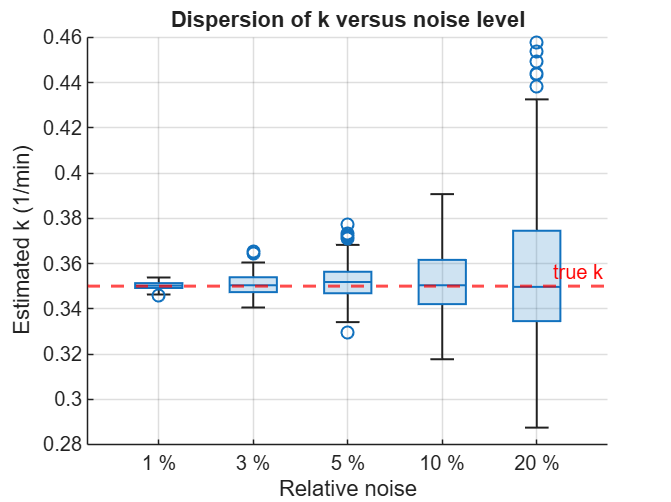

grp = categorical(repelem(sigmas*100, Nmc)', sigmas*100, string(sigmas*100) + " %");

figure;
boxchart(grp, k_est(:)); hold on
yline(k_true, 'r--', 'true k', 'LineWidth', 1.5);
xlabel('Relative noise'); ylabel('Estimated k (1/min)'); grid on
title('Dispersion of k versus noise level');
exportgraphics(gcf, 'figures/fig02_noise_boxplot.png', 'Resolution', 300);

## 11. Estimation of k0 and Ea: Arrhenius law

We simulate isothermal experiments at five temperatures. For each temperature, the observation time is adapted to the reaction rate (4/k, about four time constants): this is an experimental design choice. Two methods are compared:

Method A (two steps): k is fitted at each temperature, then a linear regression of ln k versus 1/T is performed. The slope equals -Ea/R and the intercept equals ln k0.

Method B (global fit): kref and Ea are fitted directly on all the data at once, using the reparametrization around Tref. Residuals are taken in logarithmic form because the noise is relative, which gives the same weight to all points.

rng(3);
k0_true = 1e7;  Ea_true = 50e3;      % 1/min ; J/mol
Tvec = [300 310 320 330 340]';       % K
Tref = 320;  sigma_T = 0.03;
kT_true = k0_true*exp(-Ea_true./(R*Tvec));

tcell = cell(size(Tvec));  Ccell = cell(size(Tvec));
for i = 1:numel(Tvec)
    tcell{i} = linspace(0, 4/kT_true(i), 15)';
    C = CA0*exp(-kT_true(i)*tcell{i});
    Ccell{i} = max(C.*(1 + sigma_T*randn(size(C))), 1e-6);
end

% Method A
k_fit = zeros(size(Tvec));
for i = 1:numel(Tvec)
    k_fit(i) = lsqnonlin(@(k) model_first_order(k, tcell{i}, CA0) - Ccell{i}, ...
                         kT_true(i)*0.5, 0, [], opts_q);
end
polA = polyfit(1./Tvec, log(k_fit), 1);
Ea_A = -polA(1)*R;   k0_A = exp(polA(2));

% Method B
p0 = [log(0.05), 40];     % [ln(kref), Ea in kJ/mol]
[p_hat, ~, resid_B, ~, ~, ~, J_B] = lsqnonlin( ...
    @(p) global_residual(p, Tvec, tcell, Ccell, CA0, R, Tref), ...
    p0, [-inf 1], [inf 200], opts_q);
Ea_B = p_hat(2)*1e3;
k0_B = exp(p_hat(1))*exp(Ea_B/(R*Tref));
CI_B = nlparci(p_hat, resid_B, 'jacobian', J_B);

fprintf('                Ea (kJ/mol)    k0 (1/min)\n');

                Ea (kJ/mol)    k0 (1/min)


fprintf('True            %8.2f     %.3e\n', Ea_true/1e3, k0_true);

True               50.00     1.000e+07


fprintf('Method A        %8.2f     %.3e\n', Ea_A/1e3, k0_A);

Method A           50.15     1.058e+07


fprintf('Method B        %8.2f     %.3e\n', Ea_B/1e3, k0_B);

Method B           49.94     9.797e+06


fprintf('95 %% CI of Ea (method B): [%.1f ; %.1f] kJ/mol\n', CI_B(2,1), CI_B(2,2));

95 % CI of Ea (method B): [49.8 ; 50.1] kJ/mol


fprintf('True Ea within the CI: %s\n', string(Ea_true/1e3 >= CI_B(2,1) && Ea_true/1e3 <= CI_B(2,2)));

True Ea within the CI: true


## 12. Arrhenius plot

When ln k is plotted versus 1000/T, the Arrhenius law gives a straight line. The points are the k values estimated at each temperature, the red line is the regression of method A and the blue curve is the true law.

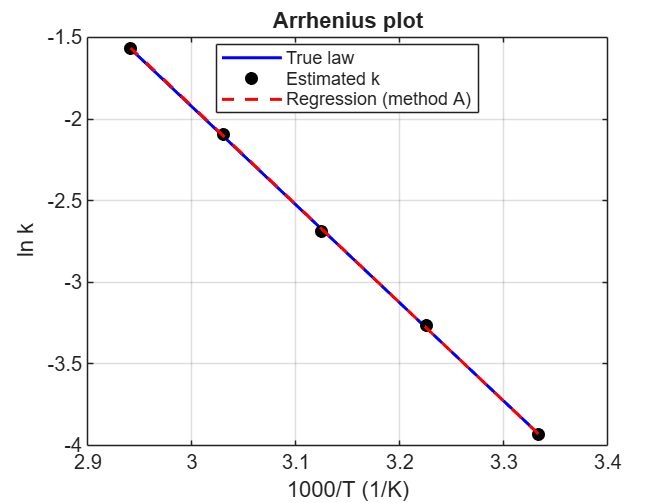

figure;
plot(1000./Tvec, log(kT_true), 'b-', 'LineWidth', 1.5); hold on
plot(1000./Tvec, log(k_fit), 'ko', 'MarkerFaceColor', 'k');
plot(1000./Tvec, polyval(polA, 1./Tvec), 'r--', 'LineWidth', 1.5);
xlabel('1000/T (1/K)'); ylabel('ln k'); grid on
legend('True law', 'Estimated k', 'Regression (method A)', 'Location', 'best');
title('Arrhenius plot');
exportgraphics(gcf, 'figures/fig03_arrhenius.png', 'Resolution', 300);

## 13. Extension: free reaction order

We now assume dCA/dt = -k · CA^n and estimate k and n simultaneously. The data are generated with n = 2 and k = 0.2, for three different initial concentrations (1, 2 and 4 mol/L). Using several CA0 values is essential: with a single curve, k and n compensate each other (several pairs give almost identical curves), whereas a second-order reaction slows down faster as the concentration drops, which separates the two effects.

rng(4);
k4_true = 0.2;  n4_true = 2;
CA0s = [1 2 4];
t4   = (0:0.5:10)';
data4 = cell(numel(CA0s), 1);
for i = 1:numel(CA0s)
    C = model_order_n([k4_true n4_true], t4, CA0s(i));
    data4{i} = max(C.*(1 + 0.03*randn(size(C))), 1e-6);
end

p0 = [0.1 1];  lb = [0 0.1];  ub = [inf 4];
[p4, ~, r4, ~, ~, ~, J4] = lsqnonlin(@(p) resid_n(p, t4, CA0s, data4), p0, lb, ub, opts_q);
CI4 = nlparci(p4, r4, 'jacobian', J4);
fprintf('k = %.3f (true %.3f) | 95 %% CI = [%.3f ; %.3f]\n', p4(1), k4_true, CI4(1,1), CI4(1,2));

k = 0.199 (true 0.200) | 95 % CI = [0.197 ; 0.202]


fprintf('n = %.3f (true %.3f) | 95 %% CI = [%.3f ; %.3f]\n', p4(2), n4_true, CI4(2,1), CI4(2,2));

n = 1.991 (true 2.000) | 95 % CI = [1.959 ; 2.023]


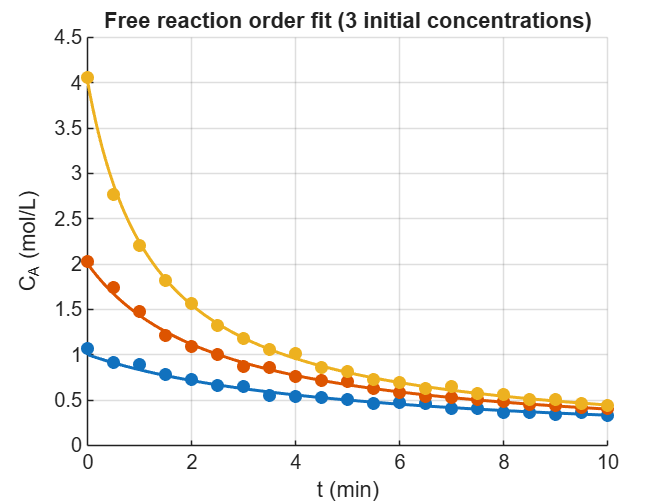


figure; hold on
colors = lines(numel(CA0s));
tf = linspace(0, 10, 200)';
for i = 1:numel(CA0s)
    plot(t4, data4{i}, 'o', 'Color', colors(i,:), 'MarkerFaceColor', colors(i,:));
    plot(tf, model_order_n(p4, tf, CA0s(i)), '-', 'Color', colors(i,:), 'LineWidth', 1.5);
end
xlabel('t (min)'); ylabel('C_A (mol/L)'); grid on
title('Free reaction order fit (3 initial concentrations)');
exportgraphics(gcf, 'figures/fig04_order_n.png', 'Resolution', 300);

## 14. Identifiability: a single initial concentration

We repeat the same fit using only the CA0 = 2 mol/L series. Compare the confidence intervals with those of the previous section.

try
    [p1, ~, r1, ~, ~, ~, J1] = lsqnonlin(@(p) resid_n(p, t4, CA0s(2), data4(2)), p0, lb, ub, opts_q);
    CI1 = nlparci(p1, r1, 'jacobian', J1);
    fprintf('Single series: k = %.3f, 95 %% CI = [%.3f ; %.3f]\n', p1(1), CI1(1,1), CI1(1,2));
    fprintf('Single series: n = %.3f, 95 %% CI = [%.3f ; %.3f]\n', p1(2), CI1(2,1), CI1(2,2));
    fprintf('Width of the CI on n: %.3f (3 series) versus %.3f (1 series)\n', ...
            CI4(2,2) - CI4(2,1), CI1(2,2) - CI1(2,1));
catch err
    fprintf('CI computation not possible with a single series: %s\n', err.message);
end

Single series: k = 0.200, 95 % CI = [0.196 ; 0.204]


Single series: n = 1.999, 95 % CI = [1.910 ; 2.089]


Width of the CI on n: 0.064 (3 series) versus 0.179 (1 series)


## 15. Discussion

Accuracy of the estimation of k. With 3 % relative noise and 16 points, the estimate of k is close to the true value and the confidence interval contains it (see section 6). This validates the model, the solver and the fitting algorithm together.

Residuals. They should be randomly scattered around zero: the model then explains all the structure in the data and only noise remains. A systematic trend would indicate an inadequate model (wrong order, missing mechanism).

Linearization versus nonlinear fit. The two methods give values of k that are close but not identical, because they do not minimize the same criterion: differences on CA for one, differences on ln CA for the other. With relative noise, the regression on ln CA is reasonable here, because it gives equivalent weight to all points. With additive noise, it would overweight the late points where CA is small. Moreover, linearization exists only for certain kinetics, whereas lsqnonlin applies to any model that can be simulated.

Effect of noise. The table and the boxplot of the Monte Carlo study show that the dispersion of k increases with the noise level. The bias should remain small compared with the standard deviation: the problem is therefore mostly one of variance. More data points or better measurements reduce the uncertainty.

Arrhenius. The global method uses all the data simultaneously, weights the points correctly and directly provides confidence intervals on Ea. The reparametrization around Tref reduces the correlation between kref and Ea and improves the conditioning of the problem. The uncertainty on Ea comes from the propagation of the uncertainties on the k values estimated at each temperature, and it depends on the temperature range explored: a narrow range would give a poorly constrained Arrhenius line and a very uncertain Ea. This effect was not simulated here and is a natural perspective.

Reaction order. Estimating k and n together is harder than estimating k alone: the two parameters are correlated. Sections 13 and 14 show that using several initial concentrations tightens the confidence intervals, which illustrates the importance of experimental design for parameter identifiability.

## 16. Limitations

- The data are synthetic: real measurements have systematic errors (calibration, sampling) that are not represented. - Closed, isothermal, perfectly mixed reactor with a single reaction: no multiple reactions, no transport limitations. - The noise is assumed Gaussian, independent and with a known relative standard deviation. - The confidence intervals assume a model that is locally linearizable around the optimum (Jacobian approximation). - The effect of the temperature range on Ea was not quantified.

## 17. Conclusion and future work

This project demonstrates a complete chain: physical model, numerical integration, parameter estimation, uncertainty quantification, validation against the analytical solution and against the true values, and finally a noise sensitivity analysis.

Future work: - Apply the method to real experimental data (for example from a lab session or an internship). - Study the effect of the temperature range and the number of points on Ea (Monte Carlo). - Handle series or parallel reactions (several species). - Use a Bayesian approach for more reliable intervals. - Reuse these building blocks in the next projects: CSTR/PFR comparison, then the exothermic CSTR.

## References

- H. S. Fogler, Elements of Chemical Reaction Engineering, Pearson. - O. Levenspiel, Chemical Reaction Engineering, Wiley. - MATLAB documentation: ode45, lsqnonlin, nlparci, boxchart.